# Orbit determination by Gauss method

clc
clear


const = orbitConst;

## observations

phi = deg2rad(40).*ones(3,1);
H = 1 .* ones(3,1); % km

t1 = 0;
t2 = 118.10;
t3 = 237.58;

t = [t1; t2; t3];

% right ascension
alp = [43.537
    54.420
    64.318];
alp = deg2rad(alp);

% declination
dlt = [-8.7833
    -12.074
    -15.105];
dlt = deg2rad(dlt);

% local sidereal time
theta = [44.506
    45.000
    45.499];
theta = deg2rad(theta);

% position vector of the observer
R = geodetic2Geocentric(phi, theta, H, const.RE, const.fE)

R = 1.0e+03 *

    3.4899    3.4302    4.0786
    3.4602    3.4602    4.0786
    3.4299    3.4902    4.0786


## Gauss method

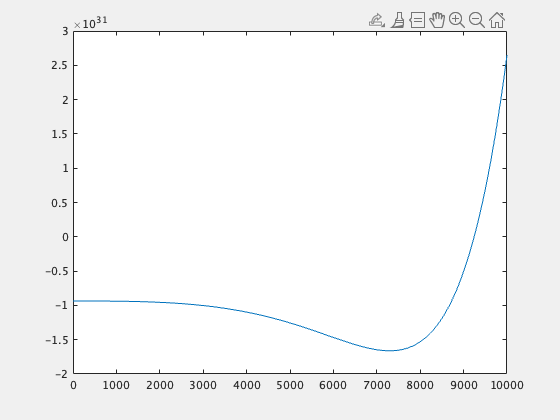

xIni = 9220

ans =    -3.8791    5.1196   -2.2409


rRange = 0:10000;
gauss(t, [alp, dlt], R, rRange, const.GE)